Interpolarea clasica va exploda din cauza **polinoamelor fundamentale** care inmultesc elemente ft mici si foarte mari, chit ca sunt **echidistante**. Avem probleme cu **overflow/underflow**, **pierderea preciziei in VF**.

Functia studiata este **foarte oscilanta**, avand **frecvente mari** si **schimbari rapide in magnitudine**.

**Interpolarea baricentrica** rezolva problema. **Balansand numaratorul si numitorul** prin introducerea **centroizilor**, *se evita* **numaratori ce se apropie de 0** sau fenomenul de **catastrophic cancellation** (*pierderea preciziei in fond*).

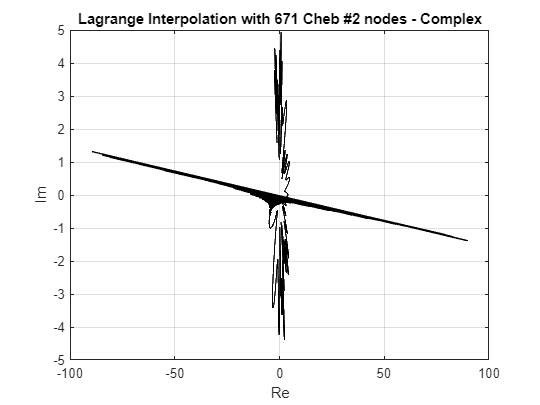

f = @(x) (3 + sin(10*pi*x) + sin(61*exp(0.8*sin(pi*x + 0.7)))) .* exp(1i*pi*x);
a = -1; b = 1;

% degree = 670 ==> 671 nodes
n = 670;

% Chebyshev #2 nodes
x_nodes = cos((0:n) * pi / n);
x_nodes = sort(x_nodes);
f_nodes = f(x_nodes);

% Evaluation points
xi = linspace(a, b, 10000);
f_exact = f(xi);

% Classic Lagrange Interpolation
Lm = Lagrange(xi, x_nodes, f_nodes);

figure;
plot(Lm, 'k');
title('Lagrange Interpolation with 671 Cheb #2 nodes - Complex');
xlabel('Re');
ylabel('Im');
grid on;

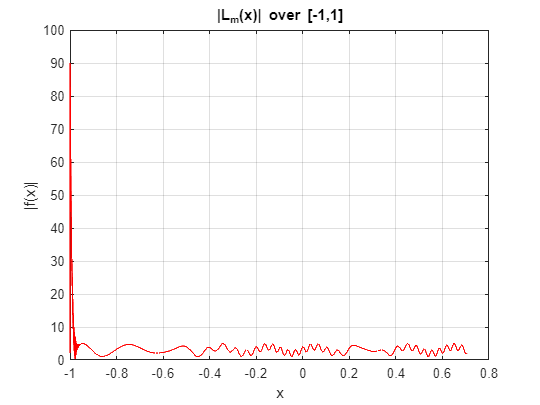


figure;
plot(xi, abs(Lm), 'r');
title('|L_m(x)| over [-1,1]');
xlabel('x'); ylabel('|f(x)|');
grid on;

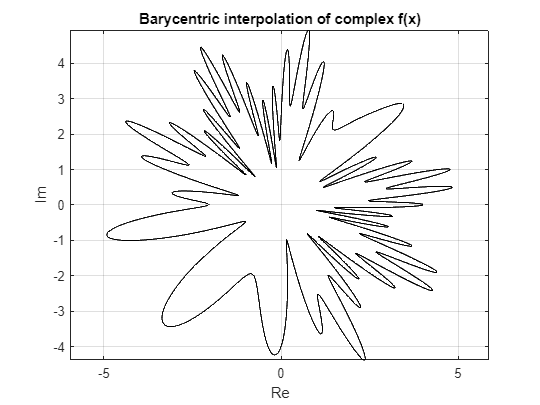


% Barycentric Interpolation
c = [1/2; ones(n-1,1); 1/2] .* (-1).^(0:n)';
B = BarycentricInterp(xi, x_nodes, f_nodes, c);

figure;
plot(B, 'k');
title('Barycentric interpolation of complex f(x)');
xlabel('Re'); ylabel('Im');
axis equal;
grid on;

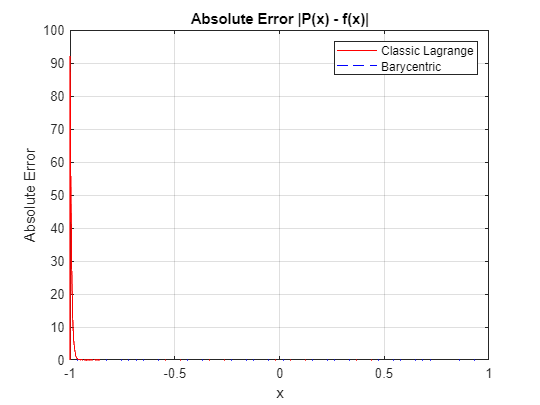


% Error analysis
error_lagrange = abs(Lm - f_exact);
error_bary = abs(B - f_exact);
rel_error_lagrange = error_lagrange ./ abs(f_exact);
rel_error_bary = error_bary ./ abs(f_exact);

% Absolute error plot
figure;
plot(xi, error_lagrange, 'r', 'DisplayName', 'Classic Lagrange');
hold on;
plot(xi, error_bary, 'b--', 'DisplayName', 'Barycentric');
title('Absolute Error |P(x) - f(x)|');
xlabel('x'); ylabel('Absolute Error');
legend; grid on;

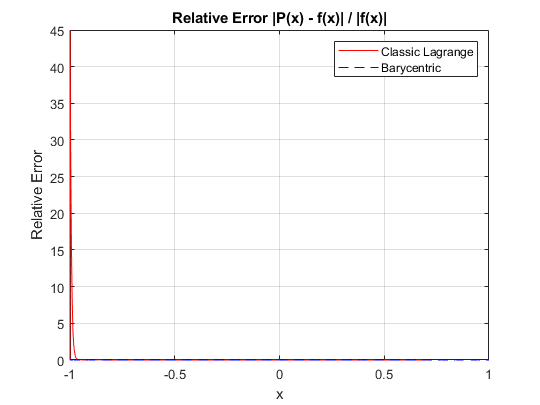


% Relative error plot
figure;
plot(xi, rel_error_lagrange, 'r', 'DisplayName', 'Classic Lagrange');
hold on;
plot(xi, rel_error_bary, 'b--', 'DisplayName', 'Barycentric');
title('Relative Error |P(x) - f(x)| / |f(x)|');
xlabel('x'); ylabel('Relative Error');
legend; grid on;

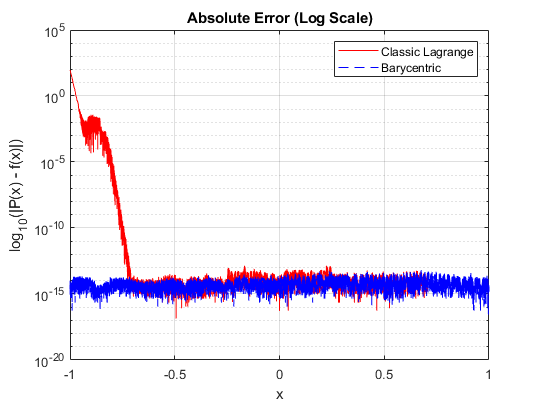


% Log-scale absolute error
figure;
semilogy(xi, error_lagrange, 'r', 'DisplayName', 'Classic Lagrange');
hold on;
semilogy(xi, error_bary, 'b--', 'DisplayName', 'Barycentric');
title('Absolute Error (Log Scale)');
xlabel('x'); ylabel('log_{10}(|P(x) - f(x)|)');
legend; grid on;